**WILL TIRONE     **

**LAB 1 **

**MAT 275 **

**Exercise 1 **

**Question 1**

format short 
theta = [0, pi/5, pi/3, pi/2, (3*pi)/2, (4*pi)/3, (5*pi)/4];
r = 4; 
x = r .* cos(theta);
y = r .* sin(theta);
radius = sqrt(x.^2 + y.^2)

radius =      4     4     4     4     4     4     4


radius == r 

ans = 1×7 logical array
   1   1   1   1   1   1   1


**Question 2**

**a) **

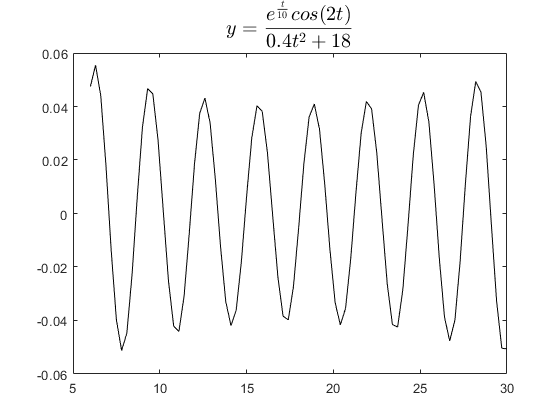

t = (6:0.3:30); 
y = (exp(t/10) .* cos(2.*t)) ./ (0.4.*t.^2 + 18); 
plot(t,y,'k'); 
title('$$y = \frac{e^{\frac{t}{10}} cos(2t)}{0.4t^2 + 18}$$','interpreter','latex',"FontSize",15,"Color",'k'); 

**b) **

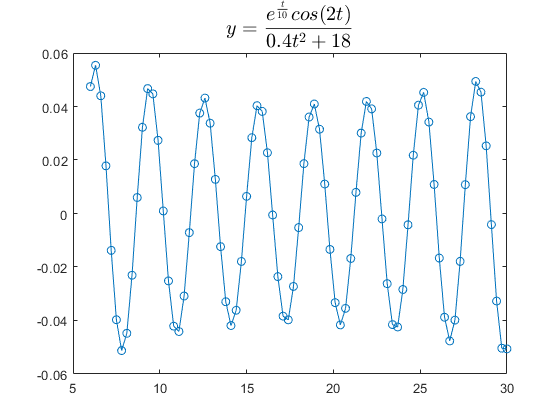

plot(t,y,'o-'); 
title('$$y = \frac{e^{\frac{t}{10}} cos(2t)}{0.4t^2 + 18}$$','interpreter','latex',"FontSize",15,"Color",'k'); 

**Question 3**

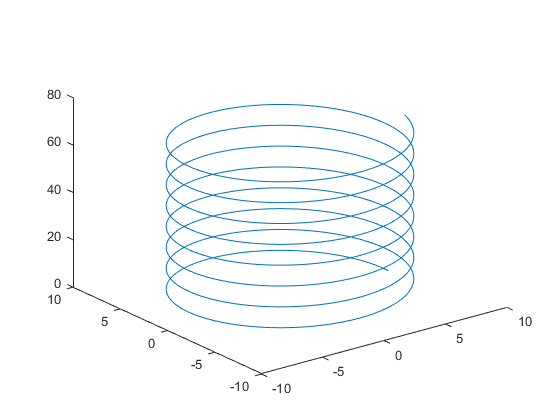

t = 0:0.01:10;
x = 8 .* cos(5.*t); 
y = 8 .* sin(5.*t); 
z = 7 .* t; 
plot3(x,y,z)

**Question 4**

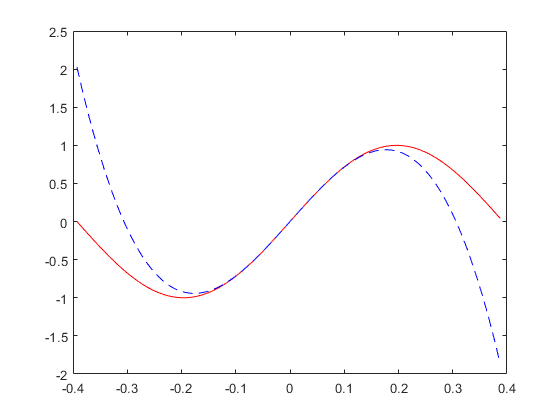

x = (-pi/8):0.01:(pi/8);
y = sin(8*x); 
z = (8.*x) - ((256/3)*x.^3 ); 
plot(x,y,'r',x,z,'b--')

**Question 5**

type ex5.m

x =0:.01:3;

y1 = f(x,10); 
y2 = f(x,15); 
y3 = f(x,25); 

plot (x,y1,'r-', x, y2, '-.k', x,y3, '--b', 'Linewidth',2); 
axis ([0 ,5 , -10 ,20]); 
grid on; 
title ("Solutions to $$\frac{dy}{dx} = 17x - 14x^2 - 7cos(x)$$",'interpreter','latex',"FontSize",15,"Color",'k'); 
legend ('C1 = 10', 'C2 = 15', 'C3 = 25') 
xlabel ('x'); ylabel ('y'); 
% -------------------------------
function y= f(x,C) 
y=(17/2).*x.^2 - (14/3).*x.^3 - 7.*sin(x) + C; 
end


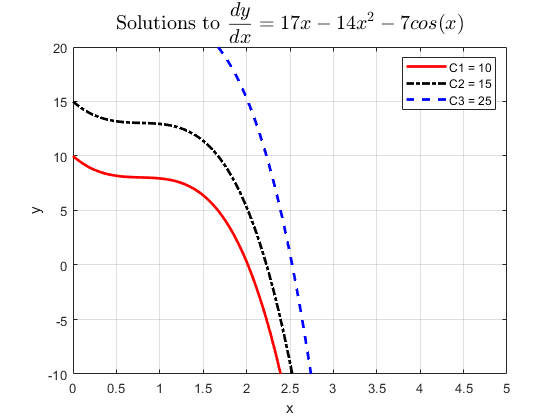

ex5

**Question 6**

**a) **

g = @(x,y)(((x^4) / (y^2)) + (cos(9*x*exp(8*y)) / ((x^6) + 2)))

g = function_handle with value:
    @(x,y)(((x^4)/(y^2))+(cos(9*x*exp(8*y))/((x^6)+2)))


g(8,6)

ans = 113.7778

**b) **

type g.m

function eval = g(x,y)
eval = ((x^4) / (y^2)) + (cos(9*x*exp(8*y)) / ((x^6) + 2)); 
end



g(8,6)

ans = 113.7778